# example of nlinfit using file name = inv_soln.m

%This program can be used as a template for most nonlinear regression OLS
%using nlinfit

## Preprocessing

s = settings;
s.matlab.fonts.editor.code.Size.TemporaryValue = '14pt';
clear % Clear the workspace.
close all; % Close all figures.
format compact

## Read in data

data =readmatrix('exp_data.xls');
x=data(:,1); %first column
yobs=data(:,2); %second column

## Initial parameter guesses

yo=100;
k=1;
beta0(1)=yo; %initial guess yo
beta0(2)=k; %initial guess kr
p=length(beta0); %p = # parameters

## define the function that will be used for the forward problem

fnameFOR = @forderdiffFOR;
%fnameFOR = @forderexpFOR;

## plot ypred with initial parameter guesses on data

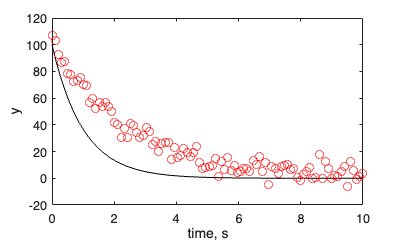

%to make sure guesses are reasonable
xs=linspace(min(x),max(x),100); %make lots of times to get a smooth curve
ns=length(xs);
ypredInit=fnameFOR(beta0,xs);
plot(xs,ypredInit,'-k',x,yobs,'or');
xlabel('time, s');
ylabel('y');

## X' = scaled sensitivity coefficients using forward-difference

%This is a forward problem with known approximate parameters

Xp=SSC_V3(beta0,xs,fnameFOR);


## plot X' for each dependent variable

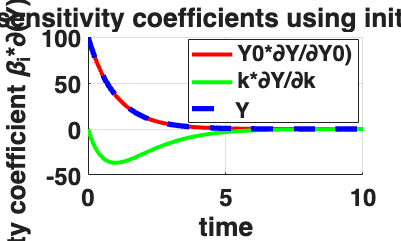

%plot for Y
cmap = ['r' 'g' 'b' 'c' 'y'  'm' 'k' ]'; %color map
figure
hold on
set(gca, 'fontsize',18,'fontweight','bold');
for i=1:p
    h2(i) = plot(xs(1:ns),Xp(1:ns,i),'-','color',cmap(i,:),'LineWidth',3);
end
%plot y vs t to know the total span
ypred=fnameFOR(beta0,xs);
h2(i+1)=plot(xs,ypred,'--','color',cmap(i+1,:),'LineWidth',4);
% legend('\beta_1*\partialY/\partial(\beta_1)','\beta_2*\partialY/\partial(\beta_2)','Y')
legend('Y0*\partialY/\partialY0)','k*\partialY/\partialk','Y','location','best')

xlabel('time'); ylabel('scaled sensitivity coefficient \beta_i*\partial(Y)/\partial(\beta_i) for Y, Y units');
title('scaled sensitivity coefficients using initial guesses')
grid on

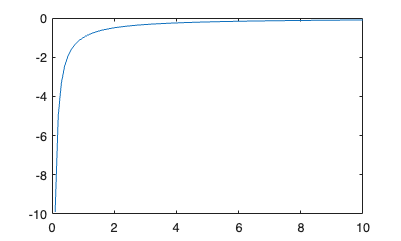

ratio=Xp(:,1)./Xp(:,2); %ratio of SSC1:SSC2
figure
plot(xs,ratio)

## nlinfit returns parameters, residuals, Jacobian (sensitivity %coefficient matrix),

%covariance matrix, and mean square error.  ode45 is solved many times iteratively

%define function to be used for inverse problem
fnameINV=@forderdiffINV;
% fnameINV=@forderexpINV;
[beta,resids,J,COVB,mse] = nlinfit(x,yobs,fnameINV,beta0);
beta %parameter estimates

beta =   102.2250    0.4060


ss=resids'*resids; %sum of squares
n=length(x); % number of data
p=length(beta); % number of parameters
rmse=sqrt(mse)  %root mean square error

rmse = 4.8411

condX=cond(J)%needs to be < 10^6.  J is the sensitivity matrix = X

condX = 241.1742

detXTX=det(J'*J) %needs to be far from zero

detXTX = 2.5055e+06

## confidence intervals for parameters

ci=nlparci(beta, resids,J)

ci =    98.4751  105.9749
    0.3844    0.4276



%R is the correlation matrix for the parameters, sigma is the standard error vector
[R,sigma]=corrcov(COVB);
R

R =     1.0000    0.6950
    0.6950    1.0000


sigma %parameter error

sigma =     1.8896
    0.0109


relerr=sigma./beta' %relative error (coefficient of variance) for each parameter

relerr =     0.0185
    0.0268


## Confidence and prediction intervals for the dependent variable

%nonlinear regression confidence intervals-- 'on' means simultaneous
%bounds; 'off' is for nonsimultaneous bounds; must use 'curve' for
%regression line, 'observation' for prediction interval
[ypred, delta] = nlpredci(fnameINV,x,beta,resids,J,0.05,'on','curve'); %confidence band for regression line
[ypred, deltaob] =nlpredci(fnameINV,x,beta,resids,J,0.05,'on','observation');%prediction band for individual points

yspan=range(ypred)% total span of ypred

yspan = 100.4619

relrmse=rmse/yspan % ratio of rmse vs. yspan

relrmse = 0.0482


%simultaneous confidence bands for regression line
CBu=ypred+delta;
CBl=ypred-delta;

%simultaneous prediction bands for individual points
PBu=ypred+deltaob;
PBl=ypred-deltaob;

## Output--ypred and yobs vs. t

figure 
hold on
ypredp=fnameFOR(beta,xs);%ypredp for plotting
set(gca, 'fontsize',20,'fontweight','bold');
h1(1)=plot(xs,ypredp,'-','linewidth',3); %predicted y values
h1(2)=plot(x,yobs,'square', 'Markerfacecolor', 'r');
xlabel('time (min)','fontsize',16,'fontweight','bold')
ylabel('y','fontsize',16,'fontweight','bold')

## Output --CIs and PIs

%plot Yobs, Ypred line, confidence band for regression line
h1(3) = plot(x,CBu,'--g','LineWidth',2);
plot(x,CBl,'--g','LineWidth',2); %no handle for lower CB

%plot prediction band for regression line
h1(4) = plot(x,PBu,'-.c','LineWidth',2);
plot(x,PBl,'-.c','LineWidth',2);%no handle for lower PB
legend(h1,'ypred','yobs','CB','PB')

## residual scatter plot

figure
hold on
plot(x, resids, 'square','Markerfacecolor', 'b','markersize',10);
YLine = [0 0]; 
XLine = [0 max(x)];
plot (XLine, YLine,'R'); %plot a straight red line at zero
ylabel('Observed y - Predicted y','fontsize',16,'fontweight','bold')
xlabel('Time (min)','fontsize',16,'fontweight','bold')
grid on
set(gca, 'fontsize',14,'fontweight','bold');
meanres=mean(resids)

meanres = 0.2975

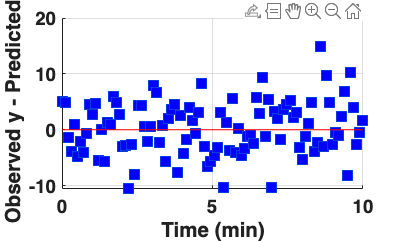

hold off

## number of runs = number of times moving from one residual to the next crosses zero

% This algorithm is good only for no replicates
% rescross=resids(2:n).*resids(1:n-1);%multiply each pair of residuals
% res_sign=sign(rescross);%get the sign of each multiplied pair
% count=0;
% for i=1:n-1
%     if res_sign(i)<0 %if product of pair is < 0, that's a run
%         count=count+1;
%     end
% end
% fprintf('number of runs = %5.2f\n',count);
% minrun=(n+1)/2; %count should be >=minrun
% fprintf('Minimum required number of runs = %5.2f\n',minrun);

% This algorithm handles replicates and no replicates
%set up matrix with col1 = x, col2 = resids
x3=x;%put x into x3
xResids = [x3 resids];
% sort residuals on time
xResidsSort=sortrows(xResids); %sorted xResids
x=xResidsSort(:,1); %sorted x
residsSort=xResidsSort(:,2); %sorted resids

count=0; %number of runs
countRep=1; %tracks number of reps 
countNeg=0; countPos=0;
resSign(countRep)=sign(residsSort(1)); %sign of first residual
for i=2:ns(end) %nS(end) is the total number of resids
    if x(i)==x(i-1) %if there is a replicate
        countRep=countRep+1;
        resSign(countRep)=sign(residsSort(i));
    else %no replicate
        %count number of positive and negative residuals
        for j=1:countRep
            if resSign(j) < 0
                countNeg=countNeg+1;
            elseif resSign(j) > 0
                countPos=countPos+1;
            end
        end
        count=count+min(countNeg, countPos);
        %Check sign of product of current resid and previous resid
        rescross=residsSort(i)*residsSort(i-1); %product of residuals
        resSign(j+1)=sign(rescross);
        if resSign(j+1) < 0
            count=count+1;
        end
        clear resSign
        countRep=1;%reset
        resSign(countRep)=sign(residsSort(i));%set resSign(1)=sign of current resids
        countNeg=0; countPos=0;
    end
end
fprintf('number of runs = %5.2f\n',count);

number of runs = 50.00


minrun=(ns(end)+1)/2; %count should be >=minrun
fprintf('Minimum required number of runs = %5.2f\n',minrun);

Minimum required number of runs = 50.50


## residuals histogram--same as dfittool, but no curve fit here

 figure
 h=histogram(resids);
% figure
%  hold on
 set(gca, 'fontsize',14,'fontweight','bold');
 xlabel('Y_{observed} - Y_{predicted}','fontsize',16,'fontweight','bold')
 ylabel('Frequency','fontsize',16,'fontweight','bold')

## scaled sensitivity coefficients using final estimated parameters

%This is a double-check to make sure X'=SSC has not changed much
clear Xp ypred
Xp=SSC_V3(beta,xs,fnameFOR);

## plot X'

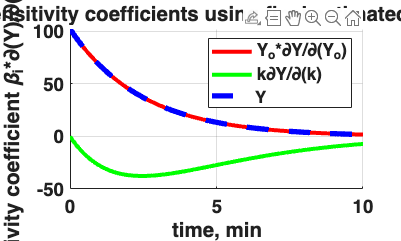

cmap = ['r' 'g' 'b' 'c' 'y'  'm' 'k' ]';
figure
hold on
set(gca, 'fontsize',14,'fontweight','bold');
for i=1:p
    h2(i) = plot(xs(1:ns),Xp(1:ns,i),'-','color',cmap(i,:),'LineWidth',3);
end
%plot C vs t to know the total span
ypred=fnameFOR(beta,xs);
h2(i+1)=plot(xs,ypred,'--','color',cmap(i+1,:),'LineWidth',4);
% legend('\beta_1*\partialY/\partial(\beta_1)','\beta_2*\partialY/\partial(\beta_2)','Y')
legend('Y_o*\partialY/\partial(Y_o)','k\partialY/\partial(k)','Y')
xlabel('time, min'); ylabel('scaled sensitivity coefficient \beta_i*\partial(Y)/\partial(\beta_i) for Y, Y units');
title('scaled sensitivity coefficients using final estimated parameters')
grid on

## functions used in this code

function y = forderdiffFOR( beta,t )
%first-order model, differential form
tspan=t; %these can be any number of times
y0=beta(1);
k=beta(2);
[t,y]=ode45(@ff,tspan,y0);

    function dy=ff(t,y) %function that computes the dydt
        dy(1)=-k*y(1);
    end
end

function y = forderexpFOR(beta,t)
%first-order reaction equation, explicit form
%beta are the parameters, and t are the independent variables values
y=beta(1)*exp(-beta(2)*t);
end


## X' = scaled sensitivity coefficients using forward-difference

This is a forward problem with known approximate parameters

function Xp=SSC_V3(beta,x,yfunc)
%Computes scaled sensitivity coefficients =Xp, nxp matrix
%can have k dependent variables that are stacked in a column vector
%all y1s, then all y2s, ...last are yks
%n is the number of data
%p is the number of parameters
%Xp1 = dY/dbeta1~[y(beta1(1+d), beta2,...betap) - y(beta1,
%beta2,...betap)]/d...
%d is the arbitrary delta, usually 0.001
%beta is the p x 1 parameter vector
%yhat is nx1 vector, the y values when only one parameter has been successively perturbed by d
%ypred is nx1 vector,  the y values when parameters are set to beta
%betain is px1 vector, the parameter values with only one parameter perturbed by d
%x are the independent variables (can be one or more independent variables)
%yfunc is a function (m file or an anonymous) defined by the user outside
%of this file
d=0.001;
ypred=yfunc(beta,x);
for i = 1:length(beta)  %scaled sens coeff for forward problem
    betain = beta; %reset beta
    betain(i) = beta(i)*(1+d);
    yhat{i} = yfunc(betain,x);
    SSC{i} = (yhat{i}-ypred)/d;%scaled sens coeff for ith parameter
    Xp(:,i)=SSC{i}; %extract from cell array to 2D array
end
end

function y = forderexpINV(beta,t)
%first-order reaction equation, explicit form
%beta are the parameters, and t are the independent variables values
y=beta(1)*exp(-beta(2)*t);
end

function y = forderdiffINV( beta,t )
%first-order model, differential form
%   called by inv_soln
tspan=t;%these are the experimental times
[t,y]=ode45(@ff,tspan,beta(1));

    function dy=ff(t,y) %function that computes the dydt
        dy(1)=-beta(2)*y(1);
    end
end